% generate figure S3
% dependence: initRSG2prior, v2struct

### set up

S=initRSG2prior;
v2struct(S); % behDir

### main loop

disp('==========');

disp('Scree plots');

Scree plots


disp('==========');

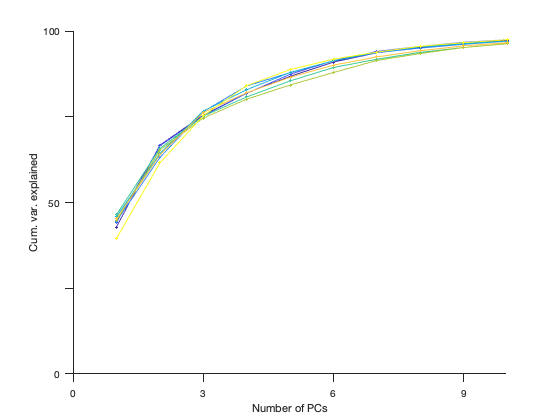

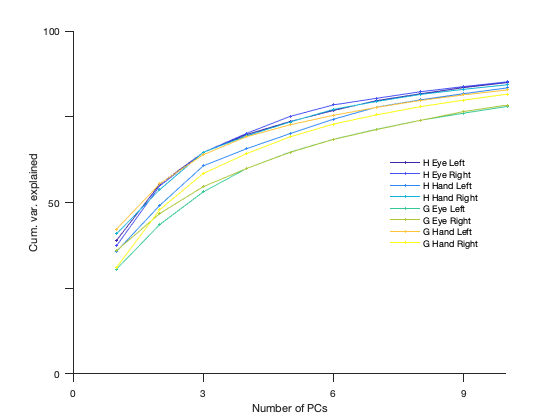

plot_scree(S); 
drawnow; pause(0.5);


disp('==========');

disp('measurement');

measurement


disp('==========');

EL_G


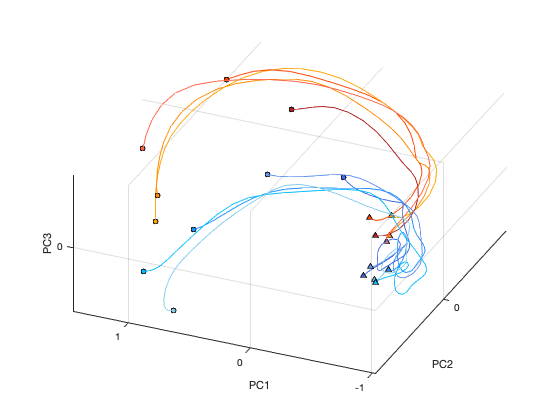

EL_H


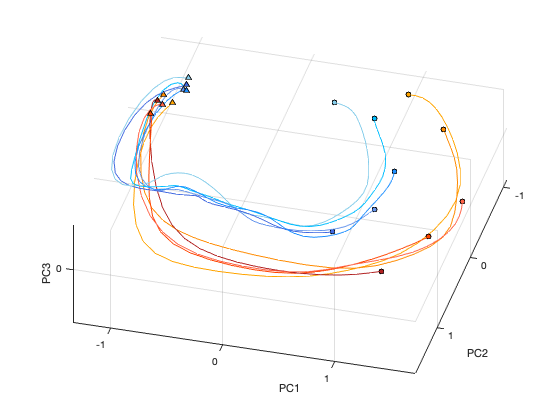

ER_G


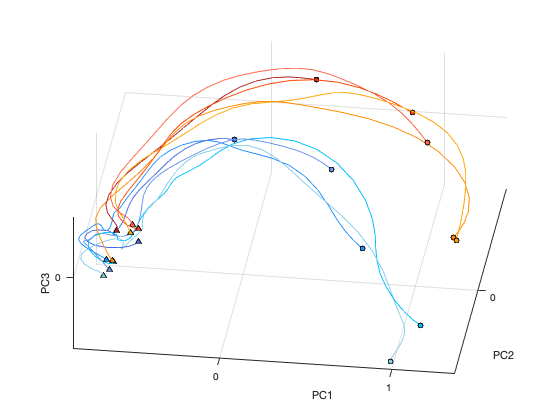

ER_H


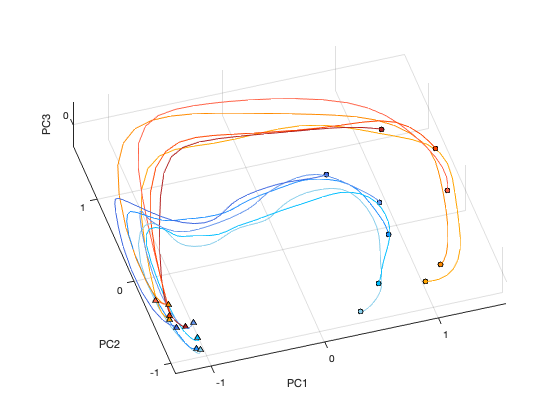

HL_G


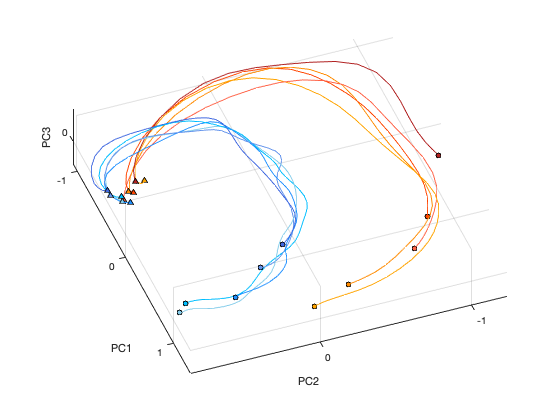

HL_H


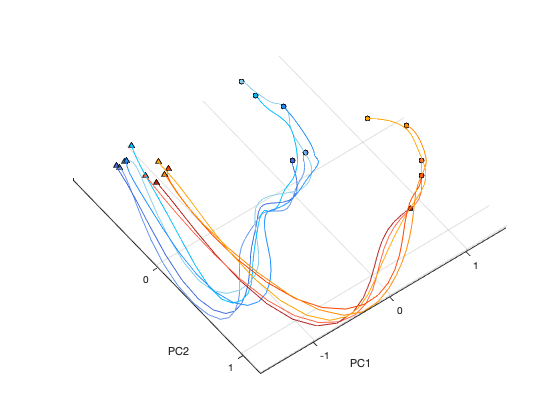

HR_G


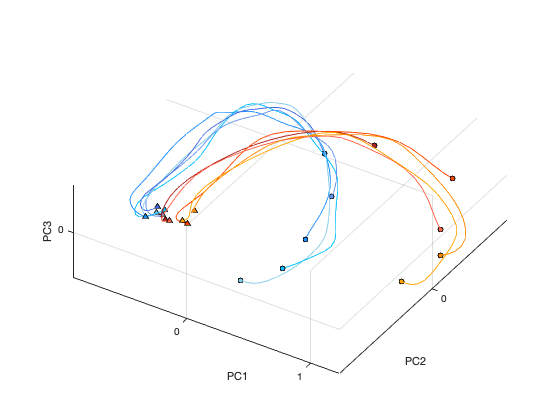

HR_H


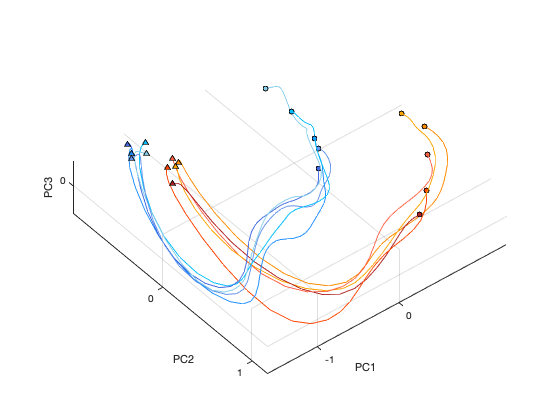

plot_traj_ts(S); 

drawnow; pause(0.5);

disp('==========');

disp('production');

production


disp('==========');

EL_G


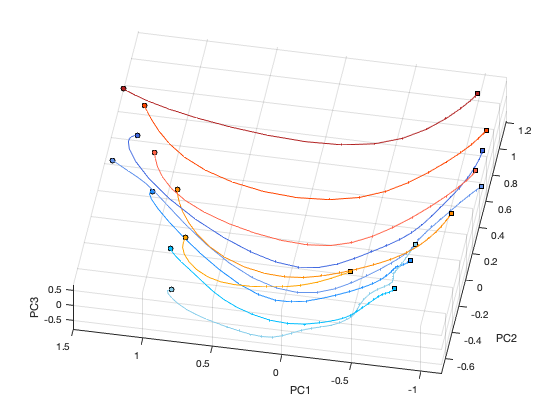

EL_H


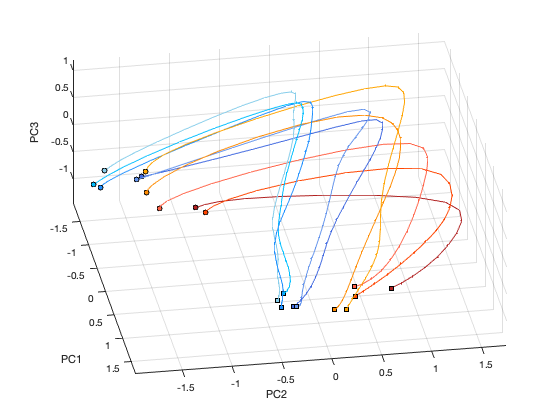

ER_G


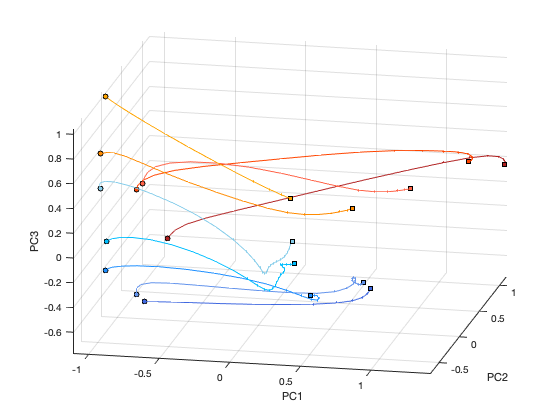

ER_H


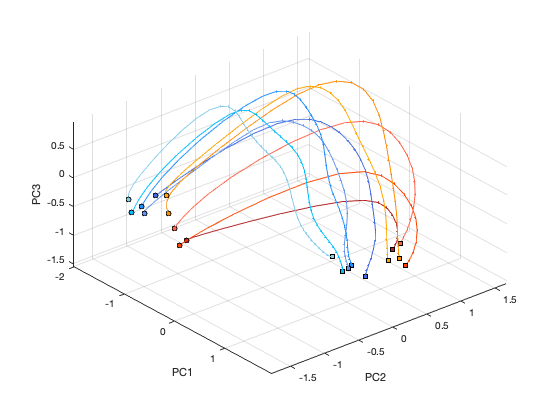

HL_G


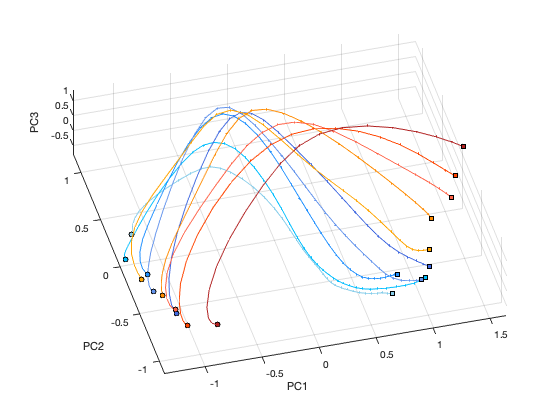

HL_H


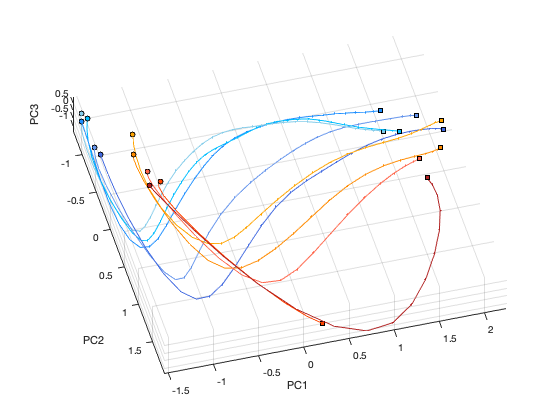

HR_G


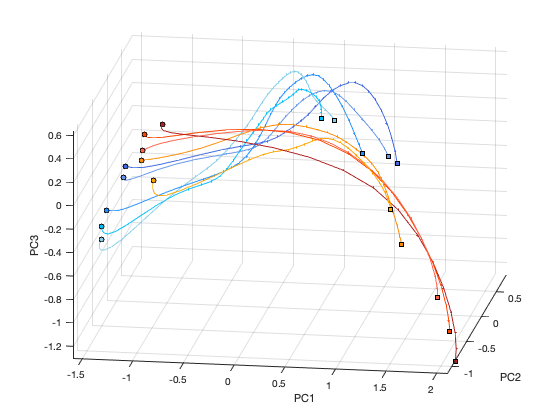

HR_H


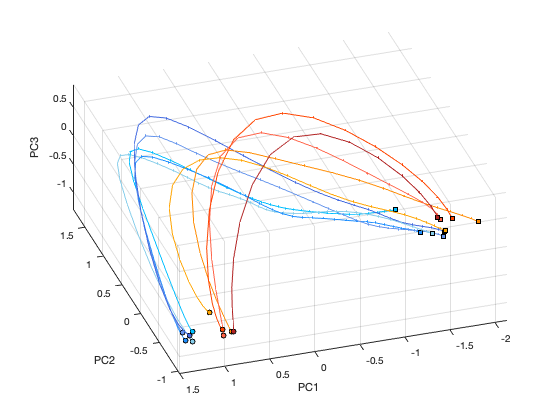

plot_traj_tp(S); 

function plot_scree(S)
v2struct(S);
condNm={'ER','EL','HR','HL'};
condNm2={'Eye Left','Eye Right','Hand Left','Hand Right'};
nCond=numel(condNm);

legendMat=cell(size(condNm));
    load pplot.mat;
    msize=2;
    lw=1;
    
    nPCmax=10;
    thVar=.75;
    
    nCmap=length(animalNm)*length(condNm);
    cmap=parula(nCmap); % hsv(nCmap);
    
    % ts
    icmap=1;
    fnTmp1='trajKS_ts_';
    figure;ha;

    for iAnimal=1:length(animalNm)
        fnTmp2=['_' animalNm{iAnimal} '_avgAttB4PCA.mat']; %_bin' num2str(binSize) '_smth' num2str(smthWidth) '.mat'];
        for i=1:length(condNm)
            load([fnTmp1 condNm{i} fnTmp2]); tmpD=load([fnTmp1 condNm{i} fnTmp2]); % eigenvalues
%             disp([fnTmp1 condNm{i} fnTmp2]);
            if isfield(tmpD,'eigenvaluesAvgAtt') % use eigenvalues from avgAtt before PCA
                plot(1:nPCmax,cumsum(eigenvaluesAvgAtt(1:nPCmax))./sum(eigenvaluesAvgAtt)*100,'o-','color',cmap(icmap,:),'markerfacecolor',cmap(icmap,:),'markeredgecolor',cmap(icmap,:),...
                    'markersize',msize,'linewidth',lw);
                optD=find(cumsum(eigenvaluesAvgAtt(1:nPCmax))./sum(eigenvaluesAvgAtt)>thVar,1,'first');
            else % if isfield(tmp,'totalVar')
                plot(1:nPCmax,cumsum(eigenvalues(1:nPCmax))./totalVar*100,'o-','color',cmap(icmap,:),'markerfacecolor',cmap(icmap,:),'markeredgecolor',cmap(icmap,:),...
                    'markersize',msize,'linewidth',lw);
                optD=find(cumsum(eigenvalues(1:nPCmax))./totalVar>thVar,1,'first');
            end
%             disp(optD);
            legendMat{icmap}=[animalNm{iAnimal} ' ' condNm2{i}]; % ':' num2str(optD) ];
            icmap=icmap+1;
        end
        xlabel('Number of PCs'); ylabel('Cum. var. explained');
        set(gca,'ytick',0:25:100,'yticklabel',{0;[];50;[];100},'ylim',[0 100],'xlim',[0 nPCmax],...
            'xtick',[0:3:9],'tickdir','out','ticklength',[.02 .02]);
        %         plot([0 3],ones(1,2)*100*sum(eigenvalues(1:3))./sum(eigenvalues),'k:');
        %
        %         plotHorizon(gca,thVar,[]);
        %         plotVertical(gca,3,[]);
%         legend(legendMat,'location','best'); legend boxoff;
    end % for iAnimal=1:length(animalNm)
%                     applytofig(gcf,optsExpFig); % plotTraj_SFN17(fnTmp);
%                 savefig(gcf,fullfile(figDir,'3','PC','screePlot_ts_avgAttB4PCA'));
%                 remAxLabel;
%                 print(gcf,fullfile(figDir,'3','PC','screePlot_ts_avgAttB4PCA.eps'),'-depsc'); % ['periSet4_measOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3.fig']);

    
    % tp
    legendMat=cell(size(condNm));
    icmap=1;
    fnTmp1='trajKS_tp_';
    figure;ha;

    for iAnimal=1:length(animalNm)
        fnTmp2=['_' animalNm{iAnimal}  '.mat']; % '_bin' num2str(binSize) '_smth' num2str(smthWidth)
        for i=1:length(condNm)
            load([fnTmp1 condNm{i} fnTmp2]); % eigenvalues
%             disp([fnTmp1 condNm{i} fnTmp2]);
            plot(1:nPCmax,cumsum(eigenvalues(1:nPCmax))./sum(eigenvalues)*100,'o-','color',cmap(icmap,:),'markerfacecolor',cmap(icmap,:),'markeredgecolor',cmap(icmap,:),...
                'markersize',msize,'linewidth',lw);
            optD=find(cumsum(eigenvalues(1:20))./sum(eigenvalues)>thVar,1,'first');
%             disp(optD);
            legendMat{icmap}=[animalNm{iAnimal} ' ' condNm2{i}]; % ':' num2str(optD) ];
            icmap=icmap+1;
        end
        xlabel('Number of PCs'); ylabel('Cum. var. explained');
        set(gca,'ytick',0:25:100,'yticklabel',{0;[];50;[];100},'ylim',[0 100],'xlim',[0 nPCmax],...
            'xtick',[0:3:9],'tickdir','out','ticklength',[.02 .02]);
        %         plot([0 3],ones(1,2)*100*sum(eigenvalues(1:3))./sum(eigenvalues),'k:');
        %
        %         plotHorizon(gca,thVar,[]);
        %         plotVertical(gca,3,[]);
        legend(legendMat,'location','best'); legend boxoff;
    end % for iAnimal=1:length(animalNm)
    
end

function plot_traj_ts(S) % fig3F
v2struct(S);
d=dir('trajKS_ts_*_avgAttB4PCA.mat');
for i=1:length(d)
    disp(d(i).name(11:14));
    S.fname=d(i).name; % trajKS_periSet_E2_H_bin20_smth40.mat';
    plot_traj(S);
    drawnow; pause(0.5);
end

end

function plot_traj_tp(S) % fig3G
v2struct(S);
d=dir('trajKS_tp_*_bin20_smth40.mat');
for i=1:length(d)
    disp(d(i).name(11:14));
    S.fname=d(i).name; % trajKS_periSet_E2_H_bin20_smth40.mat';
    plot_traj(S);
    drawnow; pause(0.5);
end

end


function plot_traj(S)
v2struct(S);
load(fname);

%% initial
idExpFig=0; % 1; % 0; % 1;
idKilosort=0; % 1;

if strfind(fname,'periSet') % trajKS_periSet_ER_H
    idProd=1; % 0; % 1;
    idMeas=1; % 0;
    idAtt=0; % 1; % 1; % 0;
elseif strfind(fname,'ts')
    idProd=0; % 1; % plotting together
    idMeas=1; % 0; % 1;
    idAtt= 0; % 1;
elseif strfind(fname,'tp')
    idProd=1; % plotting together
    idMeas=0; % 1;
    idAtt=0;
else
    idProd=1; % 1; % plotting together
    idMeas=0; % 0; % 1;
    idAtt= 0; % 1;
end

if idKilosort
    fnmEnd='_Kilosort';
else
    fnmEnd=[];
end
idFlipPC3=0; % 1;
idCondSpecific=true; % false;
conditionSpecificPCANm={'condSpecPCA'};
load pplot.mat; % tmpCmap

% figure's PaperUnits: 'inches'
optsExpFig.Height=4.2/2.54; % 2*1.2; % 0.8; % '1.2'; % '2'; % 7;
optsExpFig.Width=4.2/2.54; % 3.6; % 1.5*1.2*2; % '2.4'; % '4';
optsExpFig.FontSize='6';
optsExpFig.FontMode='fixed';
optsExpFig.Format='eps'; % 'tiff'; % 'pdf'; % 'png';
optsExpFig.LockAxes=1;
optsExpFig.LineMode='fixed'; % 'scaled';
%     optsExpFig.LineWidthMin=0.5;
%     optsExpFig.LineWidthMax=1.5;
optsExpFig.LineWidth=.5; %1;
optsExpFig.Renderer='painters';
lw=1; % 1.5;
lw2=1;
msize=5; % 10; % 4;
msize2=1;

nPr=2;    prNm={'Short','Long'};
nEH=2;ehNm={'Eye','Hand'};
nTarg=2; targNm={'Right','Left'}; % [0 180]
nTs=5;
nSplit=2; splitNm={'bias+','bias-'}; % more/less biased; for ts@prior mean, early/late


epNm={'fixation';'targetOn';'periReady';'periSet';'production';'ts';'tp';'_priorS_';'_priorL_';'_priorSL_';'t_s';'t_p';'prior'};
epNm2={'preFix','postFix';'preTOn','postTOn';'preReady','postReady';'','';'prod','postProd';'','';'','';'','';'','';'','';'','';'','';'',''};
for i=1:length(epNm)
    if ~isempty(strfind(fname,epNm{i})), break; end;
end
idEp=i;

animalNm={'H','G'}; % ,'t_s','t_p'};
for i=1:length(animalNm)
    if ~isempty(strfind(fname,['_' animalNm{i} '_'])), break; end;
end
idAnimal=i;

condNm={'ER','EL';'HR','HL';'E2','H2'};
for iEH=1:size(condNm,1)
    for iTh=1:nTarg
        if ~isempty(strfind(fname,condNm{iEH,iTh})),
            idCondSpecific=true; tmpId=[iEH; iTh];
            break;
        end;
    end
end
if ~exist('tmpId','var') % for RNN
    iEH=1;iTh=1;tmpId=[iEH; iTh];
end
% individual sessions' data
if ~isempty(strfind(fname,'_prior_')) % & ~isempty(strfind(fname,'avgDir'))
    tmpCmap{end+1,1}=[0 0 1;0 0 1;0 0 1;0 0 1;0 0 1]; % tmpCmap{1,1};
    linestyle={'-','-','--'};
else
    linestyle={'-','-'};
end % if ~isempty(strfind(fname,'prior')) & ~isempty(strfind(fname,'avgDir'))
% no set

if ~isempty(strfind(fname,'noSet'))
    idNoSet=1;
    linestyle{end+1}='-';
else
    idNoSet=0;
end

%% main
condId=1; % eyeRight
for iEH=1:nEH
    for iTh=1:nTarg
        if idCondSpecific
            tmpD=D;iEH=tmpId(1);iTh=tmpId(2);
            if iEH>2, iEH=2; end; % E2, H2 avgDir
        else
            tmpD=D(condId:4:length(D));
        end
        
        tmpMin=[]; % for setting measure/produce in the same range
        tmpMax=[];
        
        diffV=[];
        sSet=[]; % for curvature
        sSetAll=[]; % all data (binSize20) except before 1st set
        
        if idMeas
            hFig=figure;hold all;
            
            % H
            if idAnimal==1
                if strfind(fname,'periSet')
                    set(gca,'View',[29 60]); % [49 24]);
                    grid on; % off;
                else % ts/tp
                    if strfind(fname,'_prior_')
                        if strfind(fname,'supportOnly')
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-24    12]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-18.0000  -42.4000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[   51.0000  -44.4000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[ -80.8000   37.2000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-41 -54]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-110    67.6]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[47 36]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[34 -39]); %30 -70]);
                            end
                        end
                    elseif strfind(fname,'_ts_')
                        if strfind(fname,'depth') %%%%%%
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-17.2000   79.2000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-15 -64]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[39.0000  -75.6000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[37.2000  -89.2000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-17.2000   79.2000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[-15 -64]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[39.0000  -75.6000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[37.2000  -89.2000]); %30 -70]);
                            end
                        end
                    end
                end
                
            else % G
                if strfind(fname,'periSet')
                    set(gca,'View',[57 4]);
                    grid on; % off;
                else
                    if strfind(fname,'_prior_')
                        if strfind(fname,'supportOnly')
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[-20.6000    6.8000]); %-9   -34]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ 16.4000   13.6000]); %-22   -48]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[  -66.6000   27.6000]); %5    74]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[34.8000   15.2000]); %22   -52]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[33 77]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[32 76]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-10 31]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[172 19]); %30 -70]);
                            end
                        end
                    elseif strfind(fname,'_ts_')
                        if strfind(fname,'depth') %%%%%%
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[ 7.8000   54.8000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ -203.6000  -48.8000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-32.2000  -62.8000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[-69.6000  -76.0000]); %30 -70]);
                            end
                        else
                            if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                                set(gca,'View',[ 7.8000   54.8000]); %12 -56]);
                            elseif iEH==1 & iTh==2
                                set(gca,'View',[ -203.6000  -48.8000]); % -10 -60]); % 3 -60]);
                            elseif iEH==2& iTh==1
                                set(gca,'View',[-32.2000  -62.8000]); %19 -82]);
                            elseif iEH==2 & iTh==2
                                set(gca,'View',[-69.6000  -76.0000]); %30 -70]);
                            end
                        end
                    end
                end % periSet
            end % animal
            
            for i=1:length(tmpD)
                if length(tmpD(i).epochStarts)>1
                    iSet=tmpD(i).epochStarts(2);
                else
                    iSet=size(tmpD(i).data,2);
                end
                idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2 3 3 3 3 3 [for SL]
                
                if idAtt % with attrition
                    if i~=1 & i~=(nTs+1) & ...
                            i~=(2*nTs+1) % ... % SL
                    %                         & i~=(nTs*nPr+1) & i~=nTs*nPr+nTs+1 % with                        attrition to connect % for split tp
                    if length(tmpD(i-1).epochStarts)>1
                        endPre=tmpD(i-1).epochStarts(end); % size(tmpD(i-1).data,2);
                    else
                        endPre=size(tmpD(i-1).data,2);
                    end
                    
                    tmpX=[tmpD(i-1).data(1,endPre) tmpD(i).data(1,(endPre+1):iSet)];
                    tmpY=[tmpD(i-1).data(2,endPre) tmpD(i).data(2,(endPre+1):iSet)];
                    tmpZ=[tmpD(i-1).data(3,endPre) tmpD(i).data(3,(endPre+1):iSet)];
                    elseif i>(2*nTs+1) % no plot for after avg for SL
                        tmpX=[];tmpY=[];tmpZ=[];
                    else
                        tmpX=tmpD(i).data(1,1:iSet); % PC1
                        tmpY=tmpD(i).data(2,1:iSet);
                        tmpZ=tmpD(i).data(3,1:iSet);
                    end
                    sSet=[sSet tmpD(i).data(:,iSet)]; %  1:3,iSet)];
                    
                    if rem(i,nTs)==0 % longest ts for each prior
                        tShortestTs=size(tmpD((idPr-1)*nTs+1).data,2);
                        sSetAll{idPr}=tmpD(i).data(:,tShortestTs:end);
                    end
                    
                else
                    tmpX=tmpD(i).data(1,1:iSet);
                    tmpY=tmpD(i).data(2,1:iSet);
                    tmpZ=tmpD(i).data(3,1:iSet);
                end % with attrition
                %             if i<=length(tmpD)/2 % bias+ % for split tp
                
                plot3(tmpX,tmpY,tmpZ,'-',... % ,linestyle{idPr},...
                    'color',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw); % lines tmpCmap(i,:)       iEH
                
                % for setting measure/produce in the same range
                tmpMin=min([tmpMin min(tmpD(i).data(1:3,:),[],2)],[],2); % [3 x1]
                tmpMax=max([tmpMax max(tmpD(i).data(1:3,:),[],2)],[],2);
                
            end % for i=1:length(tmpD)
            
            % marker
            for i=1:length(tmpD)
                if length(tmpD(i).epochStarts)>1
                    iSet=tmpD(i).epochStarts(2);
                else
                    iSet=size(tmpD(i).data,2);
                end
                idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2 3 3 3 3 3 [for SL]
                
                if idAtt % with attrition
                    if i~=1 & i~=(nTs+1) & ...
                            i~=(2*nTs+1) % ... % SL
                    %                         & i~=(nTs*nPr+1) & i~=nTs*nPr+nTs+1 % with                        attrition to connect % for split tp
                    if length(tmpD(i-1).epochStarts)>1
                        endPre=tmpD(i-1).epochStarts(end); % size(tmpD(i-1).data,2);
                    else
                        endPre=size(tmpD(i-1).data,2);
                    end
                    
                    tmpX=[tmpD(i-1).data(1,endPre) tmpD(i).data(1,(endPre+1):iSet)];
                    tmpY=[tmpD(i-1).data(2,endPre) tmpD(i).data(2,(endPre+1):iSet)];
                    tmpZ=[tmpD(i-1).data(3,endPre) tmpD(i).data(3,(endPre+1):iSet)];
                    
                    elseif i>(2*nTs+1) % no plot for after avg for SL
                        tmpX=[];tmpY=[];tmpZ=[];
                    else
                        tmpX=tmpD(i).data(1,1:iSet); % PC1
                        tmpY=tmpD(i).data(2,1:iSet);
                        tmpZ=tmpD(i).data(3,1:iSet);
                    end
                    if i~=1
                        diffV=[diffV tmpD(i).data(:,iSet)-tmpD(i-1).data(:,endPre)]; % [dim x 1]
                    end
                else
                    tmpX=tmpD(i).data(1,1:iSet);
                    tmpY=tmpD(i).data(2,1:iSet);
                    tmpZ=tmpD(i).data(3,1:iSet);
                end % with attrition
                
                plot3(tmpD(i).data(1,iSet),tmpD(i).data(2,iSet),tmpD(i).data(3,iSet),'o',...
                    'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                %                     'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor','w','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                if isempty(strfind(fname,'prior'))
                    plot3(tmpD(i).data(1,1),tmpD(i).data(2,1),tmpD(i).data(3,1),'^',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                    %                     'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor','w','markersize',msize,'linewidth',lw2); % marker tmpCmap(i,:)          iEH
                end
                
            end % for i=1:length(tmpD)
            
            tmp=[tmpMin tmpMax]';
            axis tight; %(tmp(:)'); % tight; %
            if max(abs(tmpMin))<10 & max(abs(tmpMax))<10
                set(gca,'tickdir','out','TickLength', [.02 .02],...
                    'xtick',unique(round(tmpMin(1):1:tmpMax(1))),'ytick',unique(round(tmpMin(2):1:tmpMax(2))),'ztick',unique(round(tmpMin(3):1:tmpMax(3))));
            end
            xlabel('PC1');ylabel('PC2'); zlabel('PC3');
            grid on;
            
            drawnow;
            
            if idExpFig
                drawnow;
                savefig(hFig,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_readySet_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.fig'])); % ['periSet4_measOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3.fig']);
                xlabel([]);ylabel([]);zlabel([]);
                exportfig(hFig,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_readySet_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.eps']),optsExpFig);%             'periSet4_measOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3_splitTp.png'],optsExpFig);
                
            end
            varargout{1}=diffV;
            varargout{2}=sSet;
            varargout{3}=sSetAll;
            
        end %  if idMeas
        
        if idProd
            %% production only
            %          if ~idMeasProd
            hFig2=figure;
            %          end
            % H
            if idAnimal==1
                if strfind(fname,'periSet')
                    set(gca,'View',[20 26]); % [26 38]);
                    grid on; % off;
                else
                    if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                        set(gca,'View',[50    44]);
                    elseif iEH==1 & iTh==2
                        set(gca,'View',[80.4000   50.2000]); % 78 59]); % 70    48]);
                    elseif iEH==2& iTh==1
                        set(gca,'View',[-162    -54]);
                    elseif iEH==2 & iTh==2
                        set(gca,'View',[15    -82]);
                    end
                end
            else
                if strfind(fname,'periSet')
                    set(gca,'View',[12 30]);
                    grid on; % off;
                else
                    if iEH==1 & iTh==1 % {'EyeLeft','EyeRight','HandLeft','HandRight'};
                        set(gca,'View',[12    24]);
                    elseif iEH==1 & iTh==2
                        set(gca,'View',[170 -80]);
                    elseif iEH==2& iTh==1
                        set(gca,'View',[9 24]);
                    elseif iEH==2 & iTh==2
                        set(gca,'View',[-15 74]);
                    end
                end
            end
            
            hold all;
            
            sSet=[];
            sIC=[]; % [length(tmpD) x 3D]
            if ~exist('binSize')
                binSize=20;
            end
            dtIC=200;
            
            tmpMin=[];
            tmpMax=[];
            
            for i=1:length(tmpD)
                if ~idNoSet | i<=nPr*nTs
                    idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
                    
                    if length(tmpD(i).epochStarts)>1
                        iSet=tmpD(i).epochStarts(2);
                    else
                        iSet=1; % tmpD(i).epochStarts(2);
                    end
                    iIC=iSet+round(dtIC/binSize);
                    
                    plot3(tmpD(i).data(1,iSet:end),tmpD(i).data(2,iSet:end),tmpD(i).data(3,iSet:end),linestyle{idPr},...
                        'color',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw); % lines tmpCmap(i,:)       iEH
                    plot3(tmpD(i).data(1,iIC:end),tmpD(i).data(2,iIC:end),tmpD(i).data(3,iIC:end),'o',...
                        'markeredgecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'linewidth',lw2,'markersize',msize2); % lines tmpCmap(i,:)       iEH
                    
                    tmpMin=min([tmpMin min(tmpD(i).data(1:3,iSet:end),[],2)],[],2); % [3 x1]
                    tmpMax=max([tmpMax max(tmpD(i).data(1:3,iSet:end),[],2)],[],2);
                    
                end
            end
            % marker
            for i=1:length(tmpD)
                if ~idNoSet | i<=nPr*nTs
                    idPr=floor((i-1)/nTs)+1; %  1     1     1     1     1     2     2     2     2     2
                    
                    if length(tmpD(i).epochStarts)>1
                        iSet=tmpD(i).epochStarts(2);
                    else
                        iSet=1; % tmpD(i).epochStarts(2);
                    end
                    sSet=[sSet; tmpD(i).data(1:3,iSet)'];
                    
                    iIC=iSet+round(dtIC/binSize);
                    if ~strfind(fname,'set2IC')
                        sIC=[sIC; tmpD(i).data(1:3,iIC)'];
                    end % if ~strfind(fname,'set2IC')
                    
                    plot3(tmpD(i).data(1,iSet),tmpD(i).data(2,iSet),tmpD(i).data(3,iSet),'o',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                    plot3(tmpD(i).data(1,end),tmpD(i).data(2,end),tmpD(i).data(3,end),'s',...
                        'markerfacecolor',tmpCmap{idPr,1}(i-(idPr-1)*nTs,:),'markeredgecolor','k','markersize',msize,'linewidth',lw2);
                    tmpMin=min([tmpMin min(tmpD(i).data(1:3,iSet:end),[],2)],[],2); % [3 x1]
                    tmpMax=max([tmpMax max(tmpD(i).data(1:3,iSet:end),[],2)],[],2);
                end
            end
            
            tmp=[tmpMin tmpMax]';
            
            if ~strfind(fname,'set2IC')
                % connecting line for sSet or sIC
                for iPr=1:nPr
                    tsId=[1:nTs]+(iPr-1)*nTs;
                    plot3(sIC(tsId,1),sIC(tsId,2),sIC(tsId,3),':','color',pplot.cmap{nPr*iPr-1},'linewidth',lw);
                end
            end % if ~strfind(fname,'set2IC')
            
            axis tight; %(tmp(:)'); % tight;
            set(gca,'tickdir','out','TickLength', [.02 .02]); % ,...
            xlabel('PC1');ylabel('PC2'); zlabel('PC3');
            grid on;
            
            if idExpFig
                drawnow;
                savefig(hFig2,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_setGo_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.fig'])); % ['periSet4_prodOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3.fig']);
                xlabel([]);ylabel([]);zlabel([]);
                exportfig(hFig2,fullfile(figDir,'3PC',['PC123_' epNm{idEp} '_setGo_' ehNm{iEH}(1) targNm{iTh}(1) '_' animalNm{idAnimal} '.eps']),optsExpFig);%             'periSet4_prodOnly_' ehNm{iEH} targNm{iTh} '_PC1PC2PC3_splitTp.png'],optsExpFig);
            end
            
            condId=condId+1;
            if idCondSpecific, break; end;
        end %   if idProd
        if idCondSpecific, break; end;
    end % targ
    if idCondSpecific, break; end;
end % EH
end